[sectn] = sectn_hexagonalSolid(d)

sectn_hexagonalSolid(d) computes the section properties for a beam of hexagonal solid cross section.

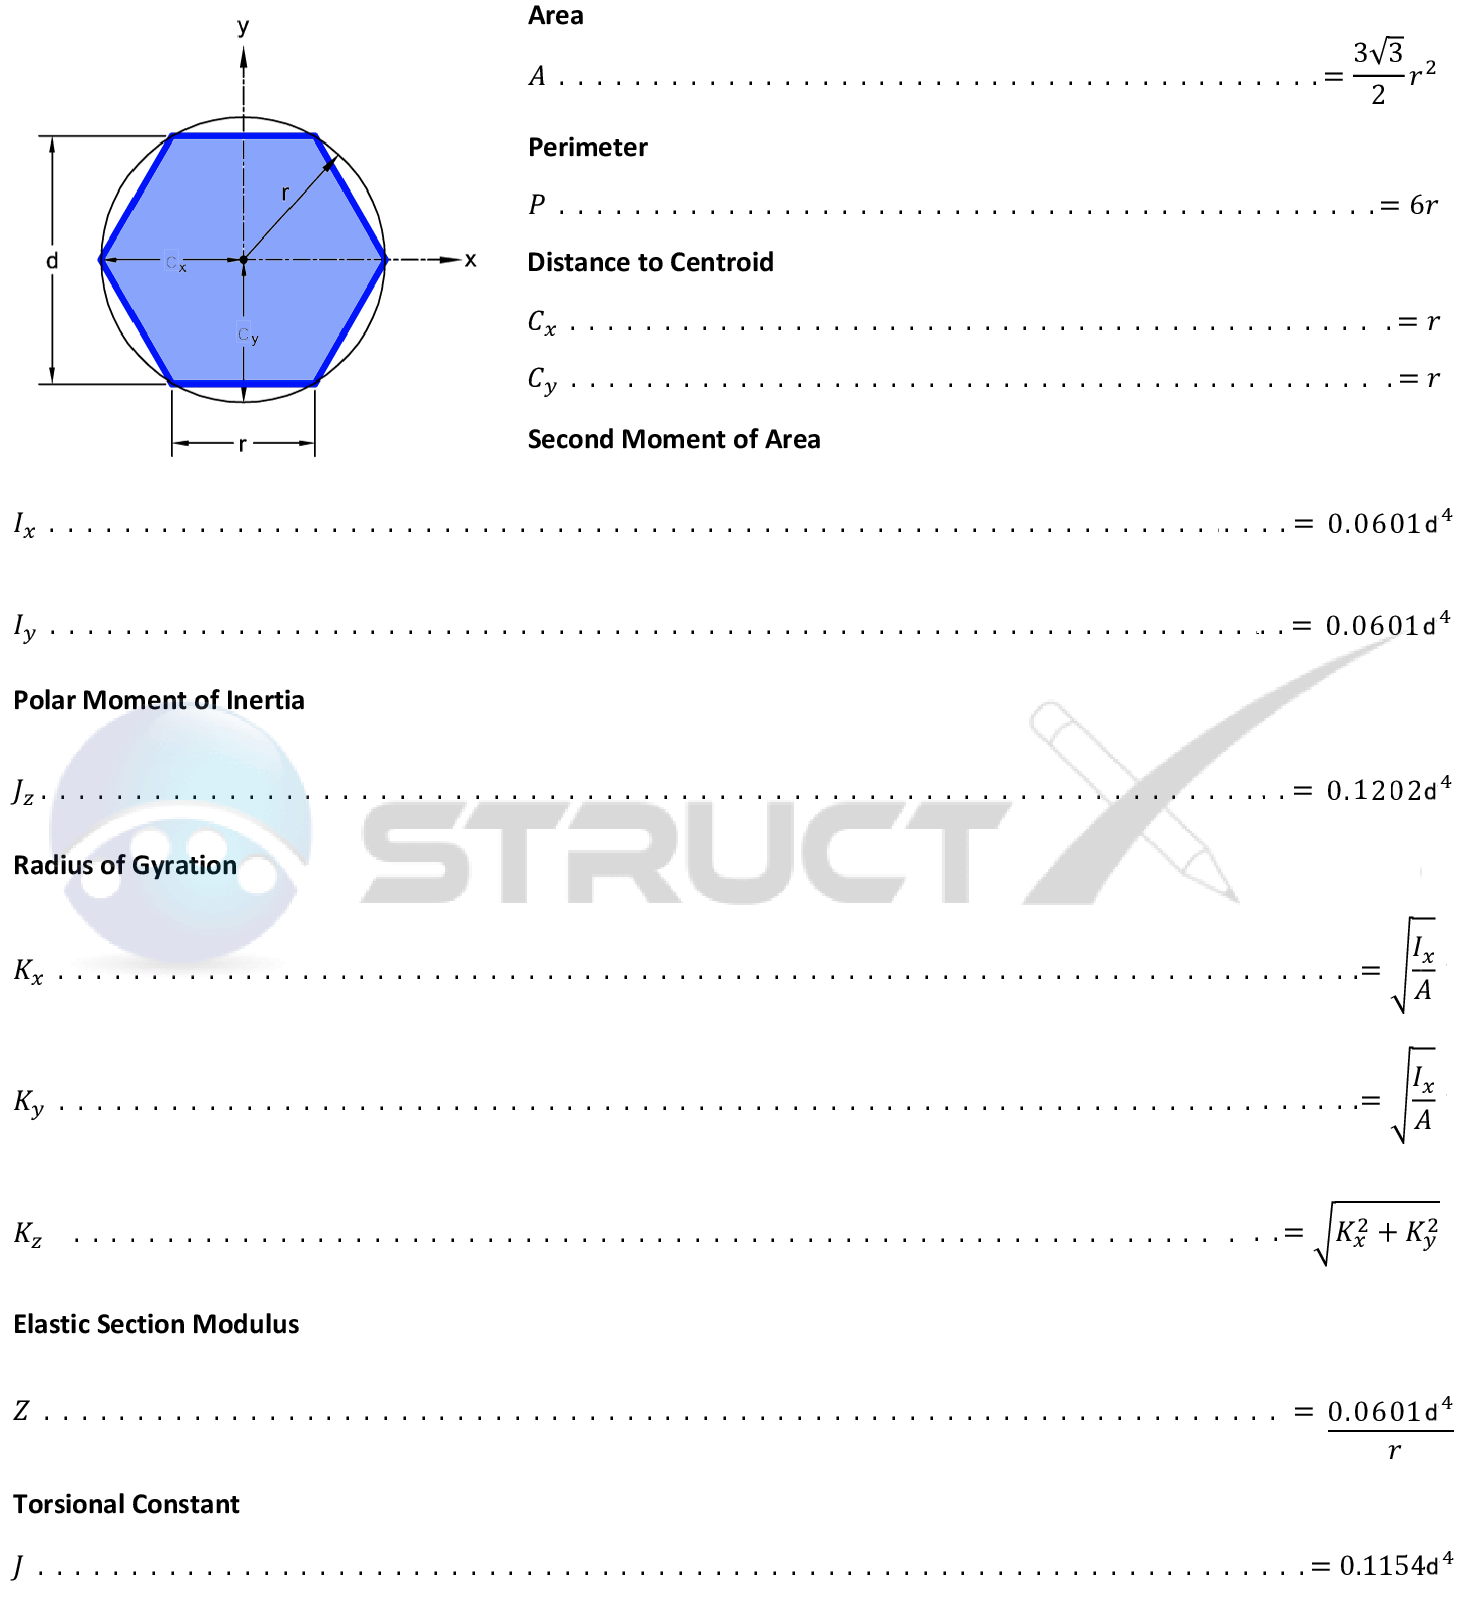

### Notation

- A = Geometric Area, in2 or mm2

- C = Distance to Centroid, in or mm

- d = Flat to flat distance = 2*apothem, in or mm

- I = Second moment of area, in4 or mm4

- Jz = Polar Moment of Inertia, in4 or mm4

- J = Torsional Constant, in4 or mm4

- K = Radius of Gyration, in or mm

- P = Perimeter of shape, in or mm

- r = Outer radius of shape = circum radius, in or mm

- Z = Elastic Section Modulus, in3 or mm3

Calling Sequence:

- [sectn] = sectn_octagonalSolid(d)

Inputs:

- d - flat to flat distance = 2*apothem, in or mm

Outputs:

- sectn - sectn data structure with updated section properties

Reference:

- https://structx.com/Shape_Formulas_036.html

function [sectn] = sectn_hexagonalSolid(d)
sectn.type = 'hexSolid';            % section type
r = d/sqrt(3);                      % circumradius
sectn.A = (3*sqrt(3)/2)*r^2;        % cross-section area
sectn.P = 6*r;                      % perimeter
sectn.C1 = r;                       % distance to centroid, axis-1
sectn.C2 = r;                       % distance to centroid, axis-2
sectn.I1 = 0.0601*d^4;              % area moment of inertia, axis-1
sectn.I2 = sectn.I1;                % area moment of inertia, axis-2
sectn.Jz = 2*sectn.I1;              % polar moment of inertia
sectn.Z1 = sectn.I1/sectn.C1;       % section modulus, axis-1
sectn.Z2 = sectn.I2/sectn.C2;       % section modulus, axis-2
sectn.K1 = sectn.I1/sectn.C1;       % radius of gyration, axis-1
sectn.K2 = sectn.I2/sectn.C2;       % radius of gyration, axis-2
sectn.J  = 0.1154*d^4;              % torsional constant
end